# PRACTICA 5: Wavelet Packets

## Ejercicio 1

#### Hacer un Live Script para practicar con wpdec, wpcoef, wprcoef, wprec, wpspectrum, besttree. Para el siguiente ejercicio generar la señal:

fs = 1000; % Frecuencia de muestreo (Num datos por seg.)
t = 0:1/fs:4; % Intervalo temporal 4 seg.
s = sin(128*pi*t).*(t<2) + sin(512*pi*t).*(t>=2);

- Con wpdec, obtener la estructura de arbol de la transformada WP de la señal de nivel 4 con ’coif5’. Representar con plot. 

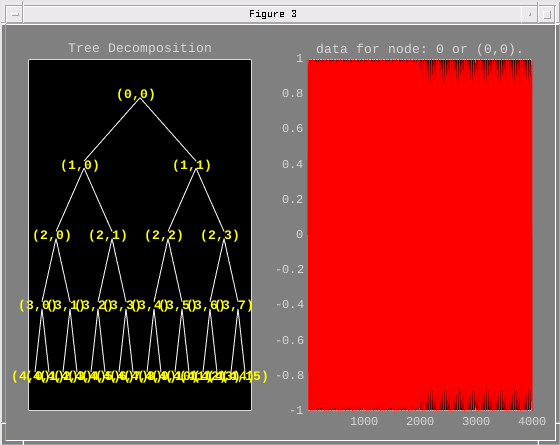

% Descomposición Wavelet Packet al nivel 4 con 'coif5'
T = wpdec(s, 4, 'coif5');

% Representar con Plot
plot(T)

- Con wpviewcf,  representar los coeficientes en orden natural y en frecuencias crecientes. 

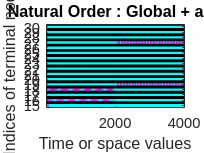

% Representación de los coeficientes en orden natural
wpviewcf(T,5);

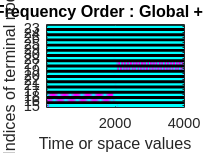


% Representación de los coeficientes en frecuencias crecientes
wpviewcf(T, 1);

- Extraer los coeficientes de los nodos (4,1) y (4,6) con wpcoef. Representar. 

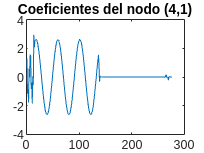

% Extraer los coeficientes del nodo (4,1)
cfs41 = wpcoef(T, [4, 1]);

% Representar los coeficientes del nodo (4,1)
figure;
plot(cfs41);
title('Coeficientes del nodo (4,1)');

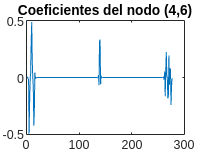


% Extraer los coeficientes del nodo (4,6)
cfs46 = wpcoef(T, [4, 6]);

% Representar los coeficientes del nodo (4,6)
figure;
plot(cfs46);
title('Coeficientes del nodo (4,6)');

- Reconstruir los nodos anteriores y representar. 

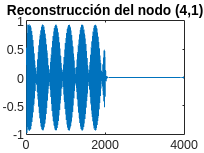

% Reconstruir el nodo (4,1)
Recons41 = wprcoef(T, [4, 1]);

% Representar la reconstrucción del nodo (4,1)
figure;
plot(Recons41);
title('Reconstrucción del nodo (4,1)');

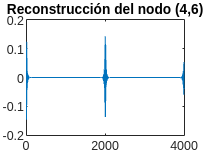


% Reconstruir el nodo (4,6)
Recons46 = wprcoef(T, [4, 6]);

% Representar la reconstrucción del nodo (4,6)
figure;
plot(Recons46);
title('Reconstrucción del nodo (4,6)');

- Obtener el ’besttree’ para la entrop´ıa de Shanon (por defecto al usar wpdec). 

% Obtener el mejor árbol (besttree) utilizando la entropía de Shannon
Tbest = besttree(T);

- Con wprec, recuperar la señal original y representarla. 

% Recuperar la señal original utilizando el mejor árbol
s_rec_best = wprec(Tbest);

% Representar la señal original recuperada con el mejor árbol
figure;
plot(s_rec_best);
title('Señal original recuperada con wprec usando Tbest');

- Con wpspectrum, obtener el espectrograma y representarlo. 

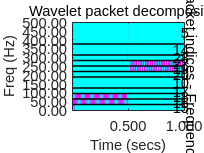

[espectro, freq, ti, tinfo] = wpspectrum(Tbest, fs, 'plot');

- Obtener las frecuencias de cada uno de los nodos.

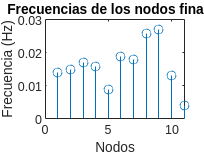

frecuencias_nodos = freq(tinfo); % Frecuencias de los nodos finales

figure;
stem(frecuencias_nodos);
title('Frecuencias de los nodos finales');
xlabel('Nodos');
ylabel('Frecuencia (Hz)');

## Ejercicio 2

#### Repetir el ejercio anterior modificando el tipo de wavelet, el nivel de descomposici´on y la entrop´ıa usada con el comando wpdec.

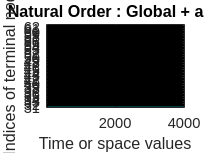

% Definición de parámetros iniciales y generación de la señal
fs = 1000; % Frecuencia de muestreo
t = 0:1/fs:4; % Intervalo temporal de 4 seg.
s = sin(128*pi*t).*(t<2) + sin(512*pi*t).*(t>=2); % Señal con dos frecuencias

% Descomposición Wavelet Packet con 'sym8' al nivel 5 y entropía de Tsallis
T = wpdec(s, 5, 'sym8', 'shannon');

% Representación de la estructura del árbol WP
figure;
plot(T);

% Representación de los coeficientes en orden natural y en frecuencias crecientes
figure;
wpviewcf(T, 5);

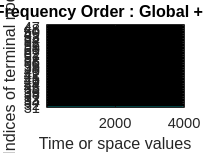

figure;
wpviewcf(T, 1);

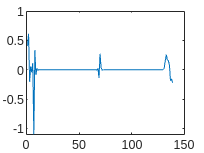


% Extracción y representación de los coeficientes de los nodos (5,1) y (5,6)
cfs51 = wpcoef(T, [5, 1]);
figure;
plot(cfs51);

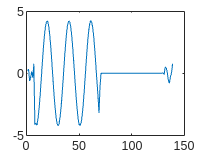

cfs56 = wpcoef(T, [5, 6]);
figure;
plot(cfs56);

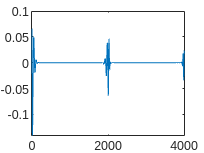


% Reconstrucción y representación de los nodos (5,1) y (5,6)
Recons51 = wprcoef(T, [5, 1]);
figure;
plot(Recons51);

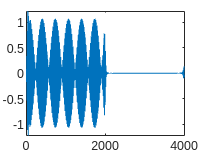

Recons56 = wprcoef(T, [5, 6]);
figure;
plot(Recons56);

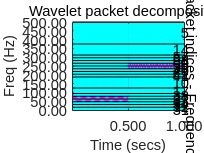


% Obtención del 'besttree' con la entropía de Tsallis
Tbest = besttree(T);

% Recuperación y representación de la señal original con wprec
s_rec_best = wprec(Tbest);
figure;
plot(s_rec_best);

% Obtención y representación del espectrograma con wpspectrum
[espectro, freq, ti, tinfo] = wpspectrum(Tbest, fs, 'plot');

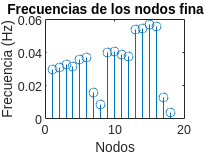


% Obtención de las frecuencias de cada uno de los nodos finales
frecuencias_nodos = freq(tinfo);
figure;
stem(frecuencias_nodos);
title('Frecuencias de los nodos finales');
xlabel('Nodos');
ylabel('Frecuencia (Hz)');

## Ejercicio 3: Analizando ’linchirp’,’quachirp’ y ’sumlichr’

#### Analizar las siguientes señales, observando los coeficientes de la descomposici´on y relacionandolos con que cada wavelet act´ua como un filtro para determinadas frecuencias. linchirp.mat, quachirp.mat, sumlichr.mat.

- Con wpdec, obtener la estructura de arbol de la transformada WP de cada una de las señales a nivel 4 con ’coif5’, ’sym4’ y con ’dmey’. 

- Representar los coeficientes en orden natural y en frecuencias crecientes. Con wpspectrum, obtener el espectrograma y representarlo. 

- ¿Qu´e conclusiones se obtienen?

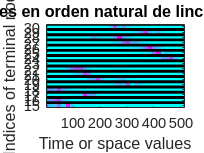

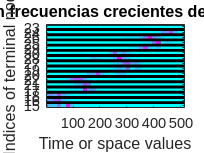

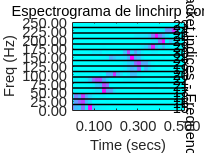

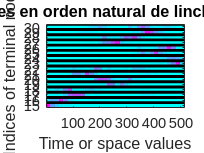

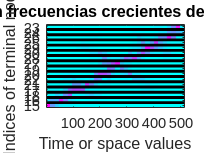

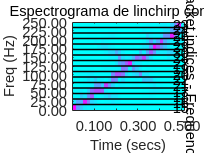

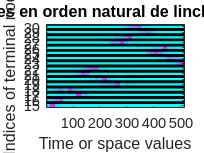

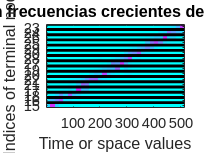

% Cargar las señales
load('linchirp.mat'); % Carga la señal linchirp
load('quachirp.mat'); % Carga la señal quachirp
load('sumlichr.mat'); % Carga la señal sumlichr

% Lista de señales y wavelets para iterar
senales = {linchirp, quachirp, sumlichr};
wavelets = {'coif5', 'sym4', 'dmey'};
nombres_senales = {'linchirp', 'quachirp', 'sumlichr'};

% Analizar cada señal con cada wavelet
for i = 1:length(senales)
    for j = 1:length(wavelets)
        % Descomposición Wavelet Packet
        T = wpdec(senales{i}, 4, wavelets{j});
        
        % Representar la estructura del árbol WP
        figure;
        plot(T);
        
        % Representar los coeficientes en orden natural (índice 5)
        figure;
        wpviewcf(T, 5);
        title(['Coeficientes en orden natural de ', nombres_senales{i}, ' con ', wavelets{j}]);
        
        % Representar los coeficientes en frecuencias crecientes (índice 1)
        figure;
        wpviewcf(T, 1);
        title(['Coeficientes en frecuencias crecientes de ', nombres_senales{i}, ' con ', wavelets{j}]);
        
        % Obtener y representar el espectrograma con wpspectrum
        figure;
        [espectro, freq, ti, tinfo] = wpspectrum(T, 500, 'plot');
        title(['Espectrograma de ', nombres_senales{i}, ' con ', wavelets{j}]);
    end
end

Ejercicio 4: Aliasing

Considerar la señal 

clear
fs = 500; t = 0:1/fs:4;
s = sin(32*pi*t.^ 3);

Calcular la transformada WP con wpdec a nivel 4 o 5 con ’dmey’. Representar los coeficientes WP con wpviewcf o obtener el espectro con wpspectrum. Modificar el factor 32 (poniendo 64, 128...) y repetir los pasos anteriores

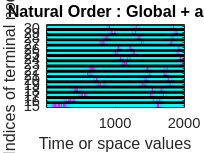

% Definición de la frecuencia de muestreo y el intervalo temporal con los nuevos parámetros
fs = 500; % Frecuencia de muestreo (Num datos por seg.)
t = 0:1/fs:4; % Intervalo temporal 4 seg.

% Generación de la nueva señal
s = sin(32*pi*t.^3);

% Calcular la transformada WP con wpdec a nivel 4 o 5 con 'dmey'
T = wpdec(s, 4, 'dmey'); % Puedes cambiar el nivel a 5 si lo prefieres

% Representar los coeficientes WP con wpviewcf
figure;
wpviewcf(T, 5);

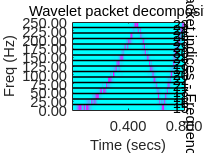


% Obtener el espectro con wpspectrum
figure;
[espectro, freq, ti, tinfo] = wpspectrum(T, fs, 'plot');

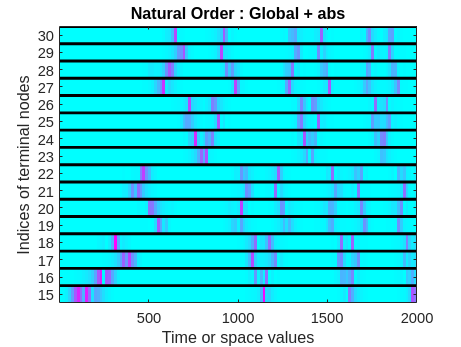

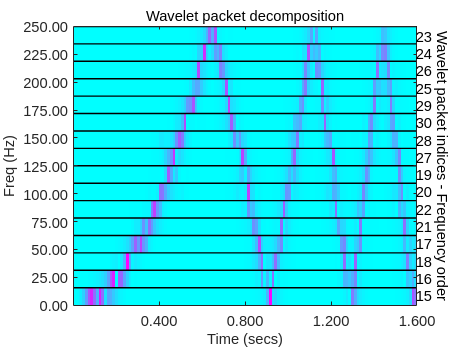

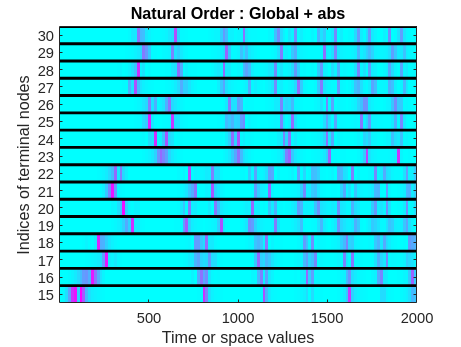

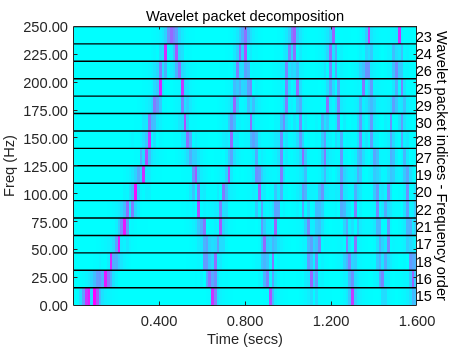


% Modificar el factor 32 (poniendo 64, 128...) y repetir los pasos anteriores
factores = [64, 128]; % Array de factores a probar
for k = 1:length(factores)
    s = sin(factores(k)*pi*t.^3);
    T = wpdec(s, 4, 'dmey');
    figure;
    wpviewcf(T, 5);
    figure;
    [espectro, freq, ti, tinfo] = wpspectrum(T, fs, 'plot');
end